clear all
close all

% System
R = 500; %Ohm
Rn = 1000;
L = 10e-3; %H
G_n = tf([Rn],[L,Rn+R]);
G_z = tf([L,R],[L,Rn+R]);

% Non coherent sampling
% sine wave with and error
fs = 1000000;
f1 = 1000;
f2 = 20000;
t = 0:1/fs:10.51/f1-1/fs;
%noise
e_range = 3.3/2^12*100; % +-7 LSB TUE
e_Uin = rand(1,length(t))*2*e_range-e_range;
% R1*sin(w1t+fi1) + R2*sin(w2t+fi2) + C
fi1 = rand(1)*pi/2;
fi2 = rand(1)*pi/2;
R1 = 1; 
R2 = 0.1;
C = 1.65;
x = R1*sin(2*pi*f1*t+fi1)+R2*sin(2*pi*f2*t+fi2)+C;
x_err = x + e_Uin;

% System output
yN = lsim(G_n,x,t)';
yN_err = lsim(G_n,x_err,t)';
yZ = lsim(G_z,x,t)';
yZ_err = lsim(G_z,x_err,t)';

%least square method x
n = length(x);
D = [cos(2*pi*f1*t)',sin(2*pi*f1*t)',cos(2*pi*f2*t)',sin(2*pi*f2*t)', ones(n,1)]; %trig identity to cos + sin for phase
DD = D'*D;
Kx = DD\D'*x_err' % least square

Kx =     0.4316
    0.9022
    0.0788
    0.0610
    1.6500


R1x_est = sign(Kx(1))*sqrt(Kx(1)^2+Kx(2)^2)

R1x_est = 1.0001

R2x_est = sign(Kx(3))*sqrt(Kx(3)^2+Kx(4)^2)

R2x_est = 0.0996

fi1x_est = atan(-Kx(2)/Kx(1))+pi/2 

fi1x_est = 0.4462

fi2x_est = atan(-Kx(4)/Kx(3))+pi/2 

fi2x_est = 0.9122


%least square method yN
KyN = DD\D'*yN_err'; % least square
R1yN_est = sign(KyN(1))*sqrt(KyN(1)^2+KyN(2)^2)

R1yN_est = 0.6654

R2yN_est = sign(KyN(3))*sqrt(KyN(3)^2+KyN(4)^2)

R2yN_est = 0.0498

fi1yN_est = atan(-KyN(2)/KyN(1))+pi/2 

fi1yN_est = 0.4017

fi2yN_est = atan(-KyN(4)/KyN(3))+pi/2 

fi2yN_est = 0.1958


%least square method yZ
KyZ = DD\D'*yZ_err'; % least square
R1yZ_est = sign(KyZ(1))*sqrt(KyZ(1)^2+KyZ(2)^2)

R1yZ_est = 0.3367

R2yZ_est = sign(KyZ(3))*sqrt(KyZ(3)^2+KyZ(4)^2)

R2yZ_est = 0.0702

fi1yZ_est = atan(-KyZ(2)/KyZ(1))+pi/2 

fi1yZ_est = 0.5341

fi2yZ_est = atan(-KyZ(4)/KyZ(3))+pi/2 

fi2yZ_est = 1.3969

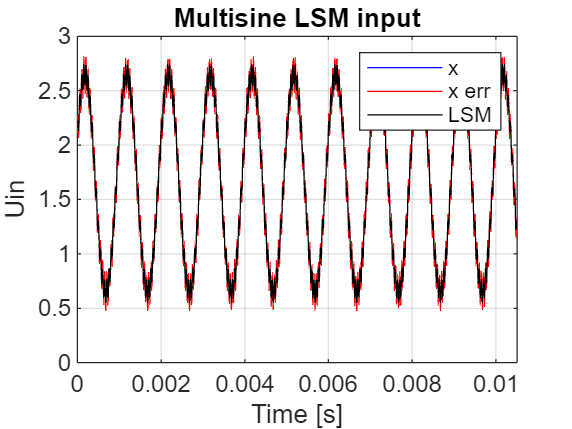


%plotting input
plot(t,x,'b')
hold on;
plot(t,x_err,'r-')
x_est = R1x_est*sin(2*pi*f1*t+fi1x_est)+R2x_est*sin(2*pi*f2*t+fi2x_est)+Kx(5);
plot(t,x_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('x','x err','LSM')
title('Multisine LSM input')

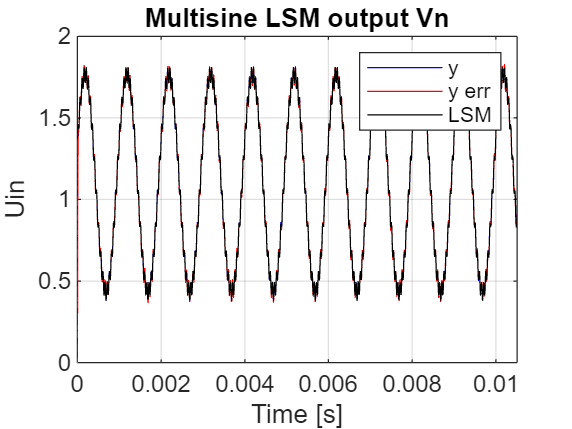


%plotting output Vn
plot(t,yN,'b')
hold on;
plot(t,yN_err,'r-')
yN_est = R1yN_est*sin(2*pi*f1*t+fi1yN_est)+R2yN_est*sin(2*pi*f2*t+fi2yN_est)+KyN(5);
plot(t,yN_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('y','y err','LSM')
title('Multisine LSM output Vn')

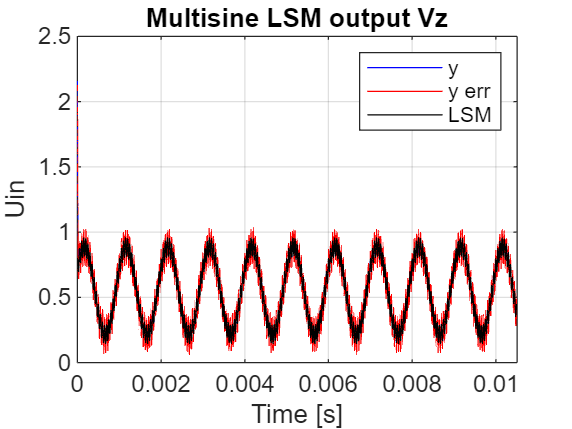


%plotting output Vz
plot(t,yZ,'b')
hold on;
plot(t,yZ_err,'r-')
yZ_est = R1yZ_est*sin(2*pi*f1*t+fi1yZ_est)+R2yZ_est*sin(2*pi*f2*t+fi2yZ_est)+KyZ(5);
plot(t,yZ_est,'k');
hold off;
grid on;
xlabel('Time [s]');
ylabel('Uin');
legend('y','y err','LSM')
title('Multisine LSM output Vz')

% Calculating impedance from LSM
G_f1 = abs(R+1j*2*pi*f1*L)

G_f1 = 503.9324

G_f2 = abs(R+1j*2*pi*f2*L)

G_f2 = 1.3525e+03

Gf_f1 = angle(R+1j*2*pi*f1*L)

Gf_f1 = 0.1250

Gf_f2 = angle(R+1j*2*pi*f2*L)

Gf_f2 = 1.1921


Za_lsm_f1 = Rn*R1yZ_est/R1yN_est

Za_lsm_f1 = 505.9516

Za_lsm_f2 = Rn*R2yZ_est/R2yN_est

Za_lsm_f2 = 1.4095e+03

Zf_lsm_f1 = fi1yZ_est-fi1yN_est

Zf_lsm_f1 = 0.1324

Zf_lsm_f2 = fi2yZ_est-fi2yN_est

Zf_lsm_f2 = 1.2011


R_lsm_f1 = Za_lsm_f1*cos(Zf_lsm_f1)

R_lsm_f1 = 501.5263

R_lsm_f2 = Za_lsm_f2*cos(Zf_lsm_f2)

R_lsm_f2 = 509.3425

L_lsm_f1 = Za_lsm_f1*sin(Zf_lsm_f1)/(2*pi*f1)

L_lsm_f1 = 0.0106

L_lsm_f2 = Za_lsm_f2*sin(Zf_lsm_f2)/(2*pi*f2)

L_lsm_f2 = 0.0105

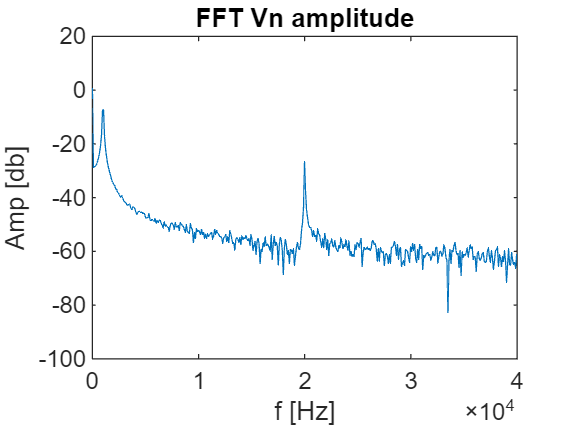

% Frequency domain, Calculating components with FFT
% Output Vn
N = length(t);
Tm = N/fs; % Tm = N*dt = N/fs
df = 1/Tm;
f = [0:df:fs-df];
f_egy = f(1:end/2);
Yn_err = fft(yN_err);
Yn_err_egyodlalas = abs(Yn_err)/length(yN_err);
Yn_err_egyodlalas = [Yn_err_egyodlalas(1),2*Yn_err_egyodlalas(2:end/2)];
Yn_err_f = angle(Yn_err(1:end/2));

% Plotting
plot(f_egy,20*log10(Yn_err_egyodlalas))
xlabel('f [Hz]')
ylabel('Amp [db]')
title('FFT Vn amplitude')
xlim([0,2*f2])

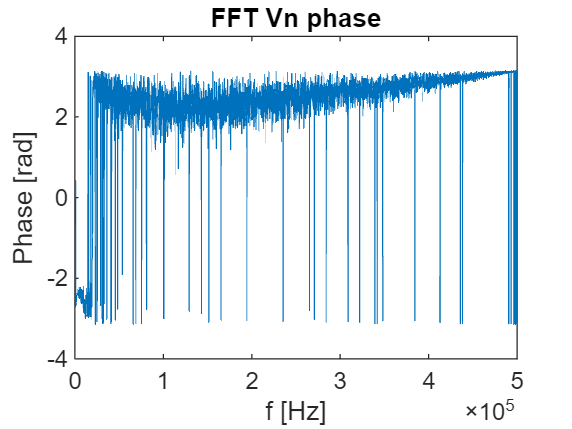

plot(f_egy,Yn_err_f)
xlabel('f [Hz]')
ylabel('Phase [rad]')
title('FFT Vn phase')

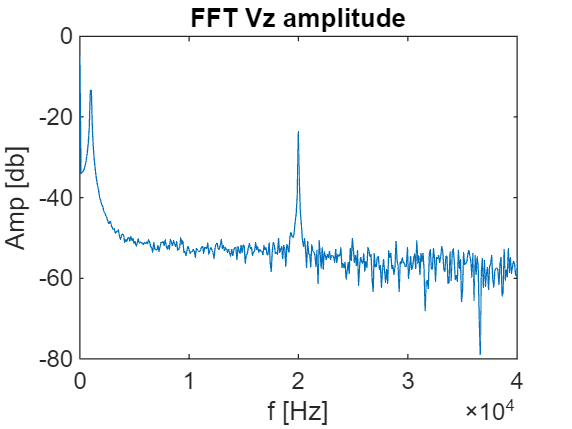



% Output Vz
Yz_err = fft(yZ_err);
Yz_err_egyodlalas = abs(Yz_err)/length(yZ_err);
Yz_err_egyodlalas = [Yz_err_egyodlalas(1),2*Yz_err_egyodlalas(2:end/2)];
Yz_err_f = angle(Yz_err(1:end/2));

% Plotting
plot(f_egy,20*log10(Yz_err_egyodlalas))
xlabel('f [Hz]')
ylabel('Amp [db]')
title('FFT Vz amplitude')
xlim([0,2*f2])

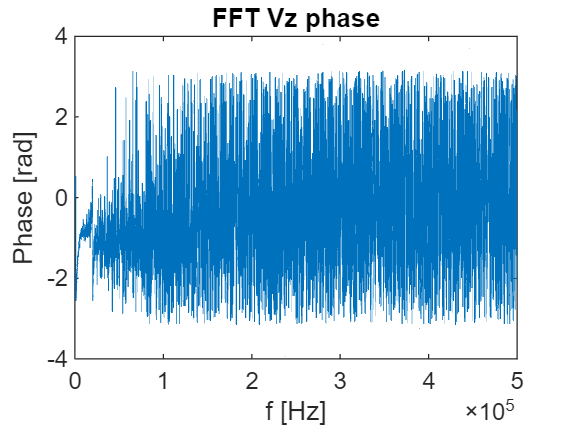

plot(f_egy,Yz_err_f)
xlabel('f [Hz]')
ylabel('Phase [rad]')
title('FFT Vz phase')

% Calculating impedance from FFT
R1yN_fft = Yn_err_egyodlalas((f_egy>f1-df/2) & (f_egy<f1+df/2));
R2yN_fft = Yn_err_egyodlalas((f_egy>f2-df/2) & (f_egy<f2+df/2));
R1yZ_fft = Yz_err_egyodlalas((f_egy>f1-df/2) & (f_egy<f1+df/2));
R2yZ_fft = Yz_err_egyodlalas((f_egy>f2-df/2) & (f_egy<f2+df/2));
f1yN_fft = Yn_err_f((f_egy>f1-df/2) & (f_egy<f1+df/2))+pi/2;
f2yN_fft = Yn_err_f((f_egy>f2-df/2) & (f_egy<f2+df/2))+pi/2;
f1yZ_fft = Yz_err_f((f_egy>f1-df/2) & (f_egy<f1+df/2))+pi/2;
f2yZ_fft = Yz_err_f((f_egy>f2-df/2) & (f_egy<f2+df/2))+pi/2;

G_f1 = abs(R+1j*2*pi*f1*L)

G_f1 = 503.9324

G_f2 = abs(R+1j*2*pi*f2*L)

G_f2 = 1.3525e+03

Gf_f1 = angle(R+1j*2*pi*f1*L)

Gf_f1 = 0.1250

Gf_f2 = angle(R+1j*2*pi*f2*L)

Gf_f2 = 1.1921


Za_fft_f1 = Rn*R1yZ_fft/R1yN_fft

Za_fft_f1 = 500.7434

Za_fft_f2 = Rn*R2yZ_fft/R2yN_fft

Za_fft_f2 = 1.3899e+03

Zf_fft_f1 = f1yZ_fft-f1yN_fft

Zf_fft_f1 = 0.1354

Zf_fft_f2 = f2yZ_fft-f2yN_fft

Zf_fft_f2 = 1.1803


Za_lsm_f1 = Rn*R1yZ_est/R1yN_est

Za_lsm_f1 = 505.9516

Za_lsm_f2 = Rn*R2yZ_est/R2yN_est

Za_lsm_f2 = 1.4095e+03

Zf_lsm_f1 = fi1yZ_est-fi1yN_est

Zf_lsm_f1 = 0.1324

Zf_lsm_f2 = fi2yZ_est-fi2yN_est

Zf_lsm_f2 = 1.2011


R_fft_f1 = Za_fft_f1*cos(Zf_fft_f1)

R_fft_f1 = 496.1581

R_fft_f2 = Za_fft_f2*cos(Zf_fft_f2)

R_fft_f2 = 529.0666

L_fft_f1 = Za_fft_f1*sin(Zf_fft_f1)/(2*pi*f1)

L_fft_f1 = 0.0108

L_fft_f2 = Za_fft_f2*sin(Zf_fft_f2)/(2*pi*f2)

L_fft_f2 = 0.0102


R_lsm_f1 = Za_lsm_f1*cos(Zf_lsm_f1)

R_lsm_f1 = 501.5263

R_lsm_f2 = Za_lsm_f2*cos(Zf_lsm_f2)

R_lsm_f2 = 509.3425

L_lsm_f1 = Za_lsm_f1*sin(Zf_lsm_f1)/(2*pi*f1)

L_lsm_f1 = 0.0106

L_lsm_f2 = Za_lsm_f2*sin(Zf_lsm_f2)/(2*pi*f2)

L_lsm_f2 = 0.0105